# Discrete LTI Model simulation

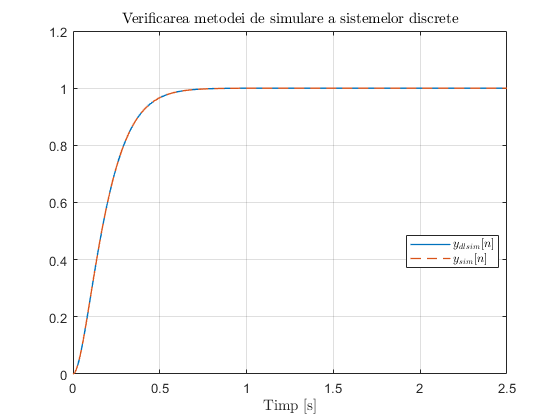

sqareWaveGen = @(t, T)((t - T*floor(t/T)) < T/2);
Kf0 = 3;
Tf0 = 7;
Te = 0.01;
T = 50*Te;
t = 0:Te:5*T;

Hf = tf(Kf0, [Tf0 1 0]);
wn = 10;
zeta = 1;
Hfd = c2d(Hf, Te, 'zoh');
[num, den] = tfdata(Hfd, 'v');

system = LinearDiscreteModel(num(2:end), den, 0);
[num, den] = getDiscreteCompensator(den(2), num(2), Te, wn, zeta);
Hcd = tf(num, den, Te, "variable", "z^-1");
controller = LinearDiscreteModel(num, den, 0);

Hd0 = feedback(Hfd*Hcd, 1);
[num, den] = tfdata(Hd0, 'v');
u = ones(length(t), 1);
ys = dlsim(num, den, u);

figure, 
plot(t, ys, "LineWidth", 1)

yss = zeros(length(t), 1);
error = zeros(length(t), 1);
command = zeros(length(t), 1);
for i = 1:length(t) - 1
    error(i) = u(i) - yss(i);
    [controller, command(i)] = controller.forward(error(i));
    [system, yss(i + 1)] = system.forward(command(i));
end

hold on;
plot(t, yss, '--', "LineWidth", 1); grid;
title("Verificarea metodei de simulare a sistemelor discrete", "Interpreter","latex");
xlabel("Timp [s]", "Interpreter","latex");
legend("$y_{dlsim}[n]$", "$y_{sim}[n]$", "Location","best", "Interpreter", "latex");

function [num, den] = getDiscreteCompensator(a1, b1, Te, Wn, zeta)
    Tf = -Te/(log(-1 - a1));
    Kf = b1/(Tf*(exp(-Te/Tf) - 1) + Te);
    ca0 = 1 + 1/(zeta*Wn*Te);
    ca1 = 1 - 1/(zeta*Wn*Te);
    cb0 = 1 + 2*Tf/Te;
    cb1 = 1 - 2*Tf/Te;
    num = (Wn/(2*Kf*zeta))*[cb0 cb1];
    den = [ca0 ca1];
    num = num/den(1);
    den = den/den(1);
end